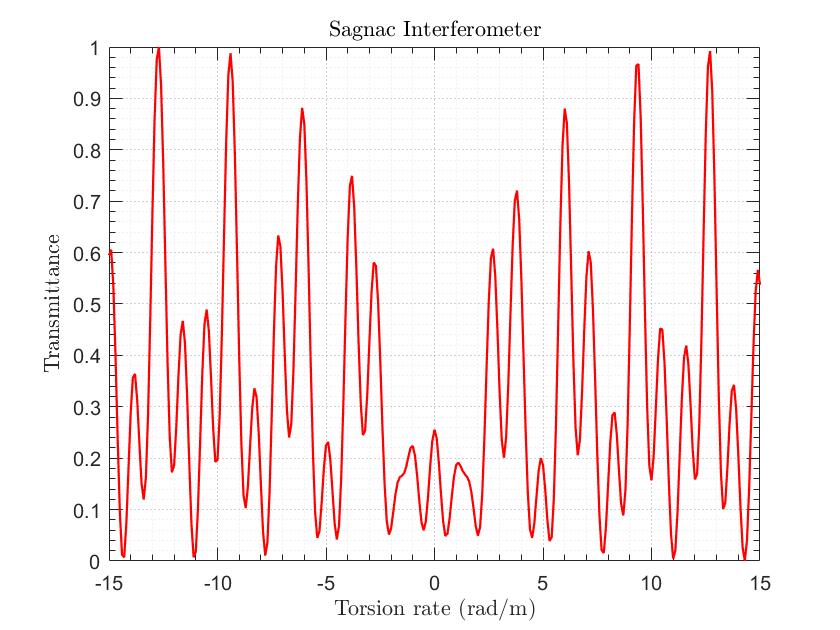

clear
close all
clc
cd C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab

lambda = 1550e-9;     % Wavelength (m)
Delta_n = 1e-7;       % Birefringence (typical for SMF-28)
Lb = lambda / Delta_n; 
L = 0.5 * Lb;         
alpha = 0.5;          % 50:50 coupling ratio
t = -15:0.1:15;       % Torsion range (rad/m)
psi0 = deg2rad(5);    % Initial rotation of axes
theta = deg2rad(5);
g = 0.16;             % Fiber parameter (silicon)

L1 = 1;               % Arm B1 length (m)
L2 = 1;               % Arm B2 length (m)

J = zeros(2,2, length(t));
I_out = zeros(1, length(t));
E1 = [1; 0];          % Input field (horizontally polarized)

for i = 1:length(t)
    % ==================================================
    % B1
    % ==================================================
    delta1B1 = (2*pi/lambda)*(L1*Delta_n);      
    deltac1 = (1-g/2)*t(i);
    eta_B1 = sqrt((delta1B1/2).^2 + (deltac1).^2);
    
    Q1 = (deltac1)*(sin(eta_B1)/eta_B1);
    P1 = cos(eta_B1) - 1j*(delta1B1/2)*(sin(eta_B1)/eta_B1);
    B1 = Bmat(P1,Q1);    

    % ==================================================
    % B2
    % ==================================================
    delta1B2 = (2*pi/lambda)*(L2*Delta_n);      
    deltac2 = (1-g/2)*t(i);
    eta_B2 = sqrt((delta1B2/2).^2 + (deltac2).^2);
    
    Q2 = (deltac2)*(sin(eta_B2)/eta_B2);
    P2 = cos(eta_B2) - 1j*(delta1B2/2)*(sin(eta_B2)/eta_B2);
    B2 = Bmat(P2,Q2);    

    % ==================================================
    % FL
    % ==================================================
    Ln = L/Lb;
    deltac = deltac1;
    eta = sqrt((pi*Ln).^2 + (psi0*Ln + deltac).^2);
    
    Q = (psi0*Ln + deltac)*(sin(eta)/eta);
    P = cos(eta) - pi*1j*Ln*(sin(eta)/eta);
    FL = Fmat(P,Q);

    C1 = C1mat(theta);
    C2 = C2mat(psi0, Ln, t(i));

    Js = B1 * C1 * FL * C2 * B2;
    J(:, :, i) = Js;

    E2 = J(:,:,i) * E1;
    I_out(i) = norm(E2)^2;  
end

I_in = norm(E1).^2;
T = I_out/I_in;
T = normData(T);

% Plot the results
figure;
plot(t, T, 'Color',[1    0 0],'LineWidth', 1.12);
xlabel('Torsion rate (rad/m)', "Interpreter","latex");
ylabel('Transmittance', "Interpreter","latex");
title('Sagnac Interferometer', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

function ND = normData(x)
    ND = (x - min(x))/(max(x) - min(x));
end

function FL = Fmat(P,Q)
    FL = [[P, conj(Q)]; [Q, conj(P)]];
end

function B = Bmat(P, Q)
    B = [[P, conj(Q)]; [Q, conj(P)]];
end

function C1 = C1mat(theta)
    C1 = [[cos(theta), -sin(theta)]; [sin(theta), cos(theta)]];
end

function C2 = C2mat(psi0, Ln, t)
    C2 = [[cos(psi0*Ln + t), -sin(psi0*Ln + t)]; [sin(psi0*Ln + t), cos(psi0*Ln + t)]];
end
